# Estimation of elastic properties of H313_HTI sample

**Author**: Abakumov Ivan, Martin Rühlmann

**Publication date**: 25th October 2019

**E-mail**: abakumov_ivan@mail.ru

## Introduction

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Upload measurements on H313_HTI sample 

Alfa1 = 90:5:270;    % two independent sets of measurements
Alfa2 = 0:5:180; 

Data = zeros(2,3,length(Alfa1),10000);

for i = 1:2  
    for j = 1:3  % 3 independent measurements
        for k = 1:length(Alfa1)
            ii = (k-1)*6 + (j-1)*2 + i;  
            filename = ['/remote/data/ivan/Ultrasonic_data/H313_HTI_ivan/org/tek' mynum2str(ii,4) 'CH2.csv'];
            data = read_csv_files(filename,15,10014);
            Data(i,j,k,:) = data(:,2);
            tt = data(:,1);
        end
    end
end



## Upload measurements on AL sample 

AData = zeros(18,10000);

for i = 1:18  
    ii = i + 222;  
    filename = ['/remote/data/ivan/Ultrasonic_data/H313_HTI_ivan/org/tek' mynum2str(ii,4) 'CH2.csv'];
    data = read_csv_files(filename,15,10014);
    AData(i,:) = data(:,2);
    tt = data(:,1);
end

AData(:,1500:end) = 0; 

for i = 1:18
   AData(i,:) = AData(i,:)/max(AData(i,:));
end

AData = mean(AData); 

take average among 3 observations

PData1 = squeeze(Data(1,:,:,:));
PData2 = squeeze(Data(2,:,:,:));
mPData1 = squeeze(mean(PData1));
mPData2 = squeeze(mean(PData2));

Amplitude normalization

nPData1 = mPData1; 
nPData2 = mPData2; 
for i = 1:length(Alfa1)
    nPData1(i,:) = mPData1(i,:)/max(mPData1(i,:)); 
    nPData2(i,:) = mPData2(i,:)/max(mPData2(i,:)); 
end

nPData = [nPData1; nPData2];
Alfa = [Alfa1, Alfa2];

Clip first arrival signal

cPData = zeros(size(nPData)); 

for i = 1:length(Alfa)
    trace = nPData(i,:);
    [~,imax] = max(trace);
    [~,imin] = min(trace);
    indc = round((imax+imin)/2);
    ind = (indc-200):(indc+200);
    cPData(i,ind) = nPData(i,ind)-0.01; 
end

## Find timeshifts

DT = zeros(length(Alfa),1);
CC = zeros(length(Alfa),1);
dt = tt(2)-tt(1);

Find timeshifts between the reference trace and all other traces

for i = 1:length(Alfa)

        trace_ref = squeeze(AData(1,:));
        trace = squeeze(cPData(i,:));
        [DT(i),CC(i)] = mycorr_hilbert(trace_ref, trace, dt);
end

Find absolute traveltiems

%Tref = 9.47e-6; % sec
%Tcor = 0.75e-6; % sec

[~,ind] = max(AData);
Tref = tt(ind); 
Tal = 0.05/6375;
Tcor = Tref - Tal;

TT = DT + Tref;

Make traveltime correction

TT = TT - Tcor;

Length of the sample 50 mm

L = 0.050;

Find phase velocities:

V = L./(TT);
V = V/1000; % (convert to km/s)

Plot the results:

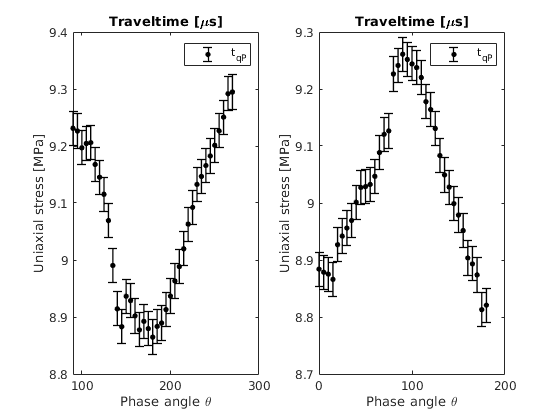

figure(1221)
subplot(1,2,1)
x_data = Alfa(1:37);
y_data = TT(1:37)'*1e6;
err_data = (0.03)*ones(size(y_data));
errorbar(x_data,y_data,err_data,'.', 'Color','black','LineWidth',1,'MarkerSize',12);
hold on
l= legend('t_{qP}');
title('Traveltime [\mus]')
ylabel('Uniaxial stress [MPa]')
xlabel('Phase angle \theta')

subplot(1,2,2)
x_data = Alfa(38:74);
y_data = TT(38:74)'*1e6;
err_data = (0.03)*ones(size(y_data));
errorbar(x_data,y_data,err_data,'.', 'Color','black','LineWidth',1,'MarkerSize',12);
hold on
l= legend('t_{qP}');
title('Traveltime [\mus]')
ylabel('Uniaxial stress [MPa]')
xlabel('Phase angle \theta')

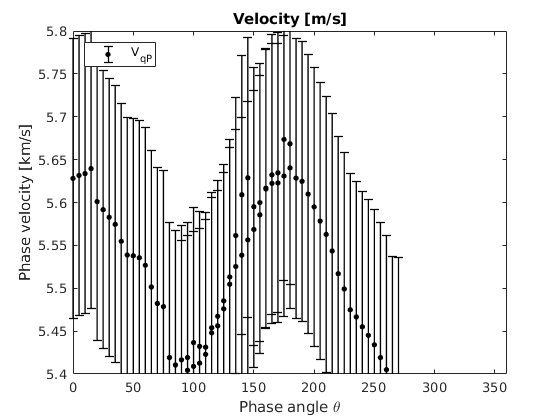





figure(1222)
x_data = Alfa;
y_data = V;
err_data = V*0.029;
errorbar(x_data,y_data,err_data,'.', 'Color','black','LineWidth',1,'MarkerSize',12);
hold on
l= legend('V_{qP}');
l.Location = 'northwest';
axis([0 360 5.4 5.8])
title('Velocity [m/s]')
xlabel('Phase angle \theta')
ylabel('Phase velocity [km/s]')


Sample.Theta  = Alfa';     % beta  [DEG] Grad
Sample.Vp33 = min(V)*ones(size(V));       % P-velocity in vertikaler (axial) "slow"
Sample.Vp11 = max(V)*ones(size(V));       % P-velocity horizontal (radial) "fast"
Sample.Vs31 = Sample.Vp33/1.7;% S-velocity vertical  (axial) "slow"
Sample.Vs21 = Sample.Vp11/1.7;% S-velocity horizontal  (radial) "fast"
Sample.Vqp = V;
Sample.rho = 2.655;

save('/remote/data/ivan/Ultrasonic_data/H313_HTI_ivan/Sample_H313_HTI_data.mat','Sample')